# This file is the parameter reading file before Simulink simulation

clear

load result_base.mat
R_load_up_req__ = R_load_up_req_;
min_frequecy_sending_system_list = zeros(1152,3);
min_Sliding_window_ROCOF_list = zeros(1152,3);
% for i = 1:1152
i = 142

i = 142

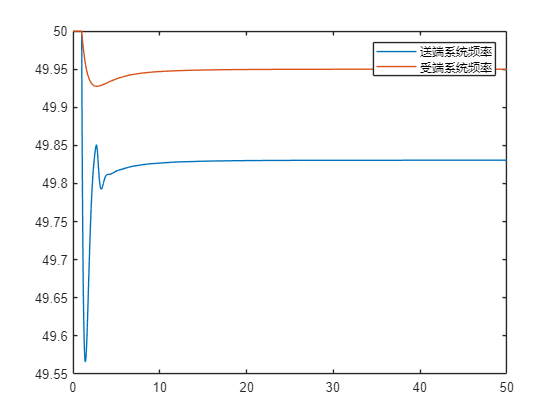

j = 3;
% 受端电力系统设置
% 火电设置
R_syn_rec = 20; %调速器下垂系数，频率下降1%，火电机组响应20倍，即20%
S_rec_syn = 65337; % 浙江（受端电网）火电机组容量MW
H_syn = 8; % 浙江（受端电网）火电机组 惯量时间常数 8s
T_ch = 0.3; % 汽轮机蒸汽容积时间常数 s
T_rh = 7; % 再热时间常数 s
T_g_syn = 0.03; %火电机组调速器等效时间常数 s：从“频率变化”到“阀门开度开始有效变化”所需的响应时间
% 水电设置
R_syn_hydra = 20; %频率下降1%，水电机组响应20倍，即20%
S_rec_hydra = 13836; % 浙江（受端电网）水电机组容量MW
H_hydra = 8; % 浙江（受端电网）水电机组 惯量时间常数 8s
T_w = 1; % 水流时间常数 s
T_g_w = 2.5; %火电机组调速器等效时间常数 s [多能互补发电系统频率控制研究]
% 电力系统设置
P_load_vsc_rec = Power_load_reshape(i,1); %送端系统中对应柔直部分的负荷（初始为7000MW）
P_load_rec = 101900; %受端电网当前总负荷（采取2022年全社会最高负荷）
S_rec = 117929; %受端电网装机容量 MW（除火电、水电外，认为核电、光伏、风电、海洋能装机不提供惯量）
H_rec = (H_hydra*S_rec_hydra+H_syn*S_rec_syn)/S_rec; %受端电网 等效惯量时间常数 s
D = 3 * P_load_rec; %自然阻尼（负荷频率特性等)  系统频率每下降1%（0.5 Hz），负荷功率会自然减少3%，从而部分抵消功率缺额
f0 = 50; %额定系统频率50Hz
% 柔直换流站（送受双端）设置
S_HVDC = 8000; % 柔直输电线路容量 MW
Udc0 = 1;
C = 0.5; %直流电容 0.5p.u.
V_base_HVDC = 800*10^3; % 柔直线路基准电压800kV
C_f = C*(S_HVDC*10^6)/(V_base_HVDC^2); % 直流电容 F
Pdc0 = P_load_vsc_rec; %直流输电功率初始值（稳态点）MW
OC_HVDC = 1.2; %柔直 过流能力 1.2倍额定容量
OC_t_HVDC = 8; %柔直 过流持续时间 8s
Kf_dc = 200; %频率波动1%，柔直功率变动200%（通过直流电容实现）
K_dc_f = 0.05; %柔直电压波动1%，送端系统频率波动0.05%；
%送端系统设置
% 电池设置
S_BES = CAP_bat/2; % 储能容量 MW
Hvirt_BES = 5; % 储能虚拟惯量时间常数 5s
P_dis_net_bat = P_dis_bat - P_ch_bat;
P_dis_bat = P_dis_net_bat(i,j); %储能初始（稳态）放电功率 MW
R_up_bat = R_UP_bat(i,j); %储能向上备用功率 MW 降负载提发电
R_down_bat = R_DOWN_bat(i,j); %储能向下备用功率 MW 降发电提负载
Kf_BES = 20; % 储能下垂系数
K_bat_vir = 10;% 自适应控制系数

% 风机设置
S_WT = CAP_WT; %送端系统 风电容量 MW
P_WT_0 = P_WT(i,j); % 送端系统 风电初始发电功率 MW
R_up_WT = R_UP_WT(i,j); %风机向上备用功率 MW 降负载提发电
R_down_WT = R_DOWN_WT(i,j); %风机向下备用功率 MW 降发电提负载
Kf_WT = 15; % 风机下垂系数

% 光伏
Hvirt_PV = 3; % 光伏虚拟惯量时间常数 3s
S_PV = CAP_PV; % 光伏装机容量 MW
P_PV_0 = P_PV(i,j); % 光伏初始发电功率 MW
R_up_PV = R_UP_PV(i,j); %光伏向上备用功率 MW 降负载提发电
R_down_PV = R_DOWN_PV(i,j); %光伏向下备用功率 MW 降发电提负载
Kf_PV = 15; % 光伏下垂系数
% 电解槽
S_EL = CAP_AKL; %电解槽装机容量 MW
P_EL_0 = Power_input_ALK(i,j); % 电解槽初始发电功率 MW
R_up_EL = R_UP_ALK(i,j); %电解槽向上备用功率 MW 降负载提发电
R_down_EL = R_DOWN_ALK(i,j); %电解槽向下备用功率 MW 降发电提负载
Kf_EL = 80;

% 初始送端功率
P_send_0 = Pdc0;
% 扰动设置
R_load_down_req_ = R_load_up_req__(i,j); %负荷跌落 474MW
R_load_up_req_ = R_load_up_req__(i,j); %负荷阶跃 MW
R_WT_up_req = R_WT_req__(i,j); %发电跌落
R_PV_up_req = R_PV_req__(i,j); %发电跌落
P_load_vsc_rec_2 = P_send_0 + R_load_up_req_;

H_send = 8; %同步机惯量时间常数
CAP_syn = [4000,2000,0];
S_send = CAP_syn(1,j);  % 1000MW 4 台  场景1对应4000MW
S_send_syn = S_send;
D_send = 0; % 送端系统阻尼系数
%滑窗时间
Sliding_window_t = 0.55; % RoCoF的滑窗时间400ms
model_name = 'FrequencySupport_OSC3';
sim_out = sim(model_name);
% 送端系统频率
t_fre = sim_out.frequecy_sending_system.time;
frequecy_sending_system = sim_out.frequecy_sending_system.signals.values;

% 送端系统RoCoF
% figure()
instant_RoCoF_sending_system = sim_out.instant_ROCOF.signals.values; %瞬时RoCoF
% plot(t_fre,instant_RoCoF_sending_system,'r')
Sliding_window_ROCOF = sim_out.Sliding_window_ROCOF.signals.values; %考虑滑窗后的RoCoF
% hold on
% plot(t_fre,Sliding_window_ROCOF,'black')
% legend('送端系统瞬时RoCoF','滑窗RoCoF')
% 送端系统
% 风电出力
wind_power = sim_out.wind_power.signals.values;
bat_dis_power = sim_out.bat_dis_power.signals.values;
pv_power = sim_out.pv_power.signals.values;
EL_power = sim_out.EL_power.signals.values;
% 直流系统
delta_P_send = sim_out.delta_P_send.signals.values; %送端系统输入到直流的功率 或者 送端VSC送出功率 的变化量（初始值时Pdc0）
Udc = sim_out.Udc.signals.values; %VSC-HVDC 直流电容电压 p.u.
P_rec = sim_out.P_rec.signals.values; %直流输出到受端的功率 或者 受端VSC送出功率
% 受端系统
frequecy_receiving_system = sim_out.frequecy_receiving_system.signals.values;
figure()
plot(t_fre,frequecy_sending_system)
hold on
plot(t_fre,frequecy_receiving_system)
legend('送端系统频率','受端系统频率')

min_frequecy_sending_system_list(i,j) = min(frequecy_sending_system);
min_Sliding_window_ROCOF_list(i,j) = min(Sliding_window_ROCOF);
% end
% 
% figure()
% plot(min_frequecy_sending_system_list(:,3))
% figure()
% plot(min_Sliding_window_ROCOF_list(:,3))
% save('result_all.mat','min_frequecy_sending_system_list','min_Sliding_window_ROCOF_list')